---

title: "PEP_wp4_beh"

output: html_document

date: "2023-12-15"

--- house keeping ---

% clear workspace
clear;
clc;

% set working directory
wd = 'C:/Users/JLU-SU/OneDrive - Justus-Liebig-Universität Gießen/Dokumente/GitHub/pep_wp4_analysis';
cd(wd);

function_folder = fullfile(pwd, 'functions')

function_folder = 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_analysis\functions'

addpath(function_folder)

--- loading files ---

% details of subjects
d.subNums = [101, 102, 103, 104, 105, 106, 109, 110, 114, 116, 117, 119, 120, 121]; 
d.n = length(d.subNums);

% add scene categories
d.categories = {'bathroom', 'kitchen'};

% load files using costum function
d = load_files(d);

    "1210"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1230"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1210"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1210"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"

    "1210"    "C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gieße…"


--- simulate additional subjects ---

% based on each subject, how many additional subjects should be simulated
sim_para.sim_subs = 10;

% Set parameters
sim_para.RT_sd = 0.3;
sim_para.acc_sd = 0.5;
sim_para.rating_sd = 0.8;
sim_para.baseline_sd = 0.2;

% use costum function to simulate data 
% d = sim_new_subs(d, sim_para);

--- timing ----

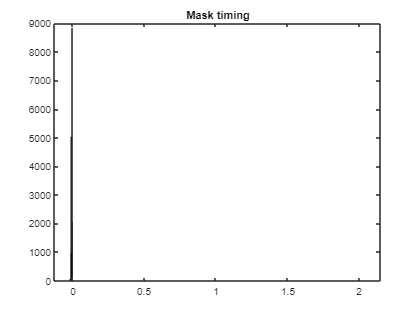

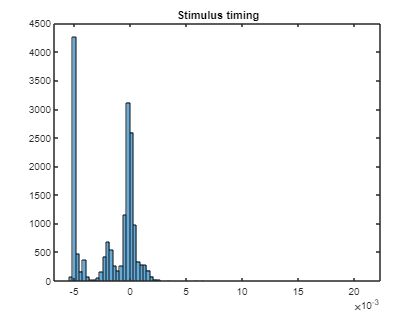

% call costum function to calculate and plot the timing
[timing, d]  = calculate_timing(d);

--- transfrom data ---

% transform data using a costum function (adds a couple new subtables)
d = transform_data(d);

% make a backup of d
d2 = d;

%% CHECK If RATING ARE CORRECT

--- performance --- 

% call a costum function to calculate performance
perf = make_perf(d);


--- HISTOGRAMS ---

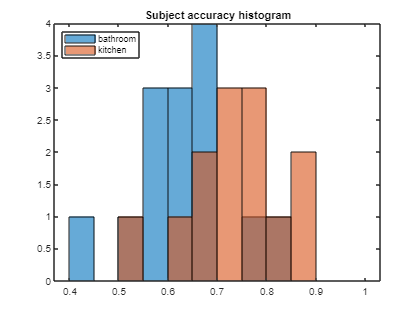

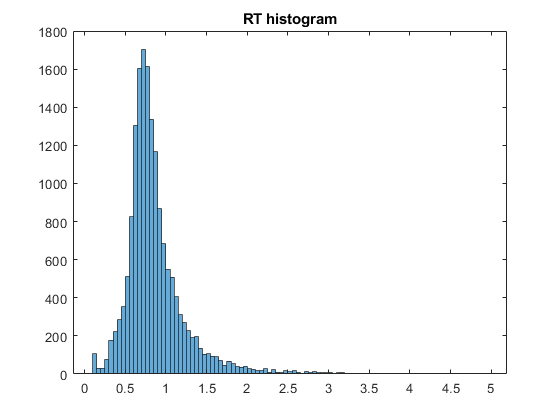

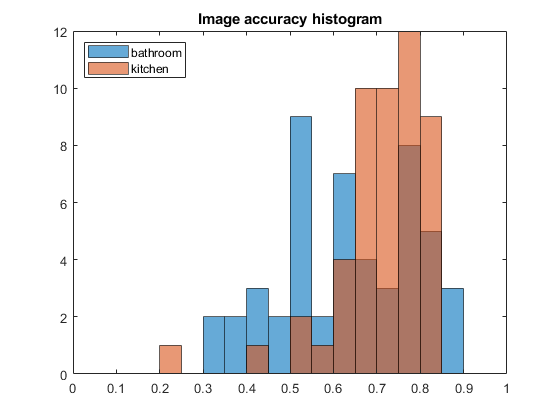

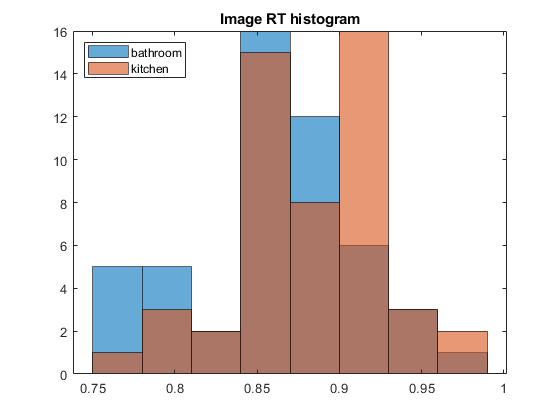

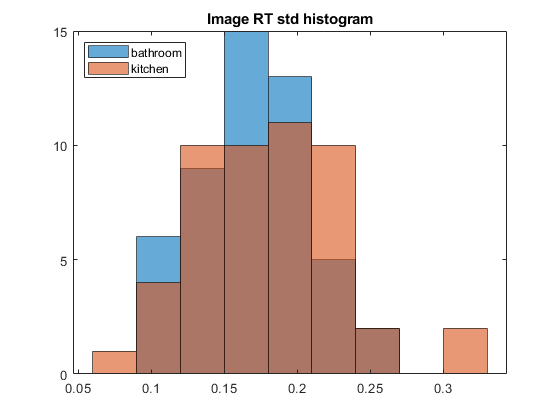

hist_plots = struct with fields:
    hist_sub_acc: [1×1 Histogram]
         hist_RT: [1×1 Histogram]
        hist_acc: [1×1 Histogram]
     hist_img_RT: [1×1 Histogram]
     hist_RT_std: [1×1 Histogram]


% call a costum function to plot histograms
hist_plots = hist_plots(d)

--- rating correlation ---

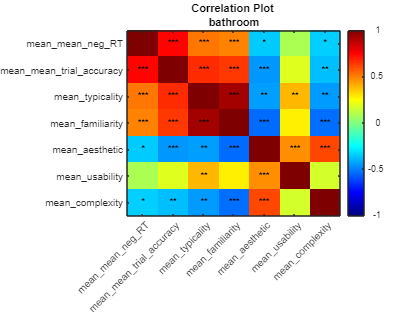

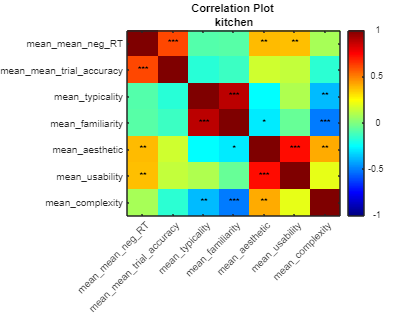

rating_rating_cor_plots = struct with fields:
    cor_plot: [1×1 Image]


% call a costum function to calculate and plot the correlations of rating on
% population level
rating_rating_cor_plots = plot_rating_cor(d)

--- intersubject correaltions ---

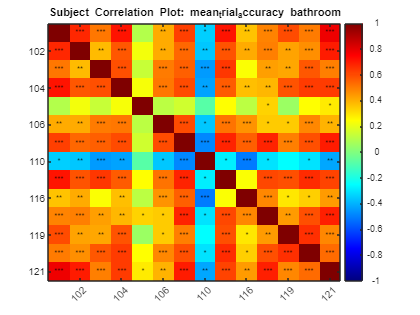

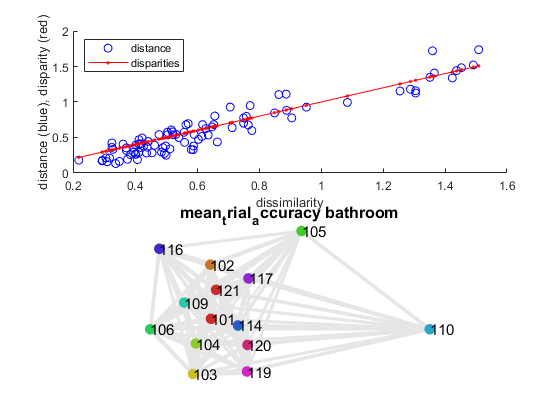

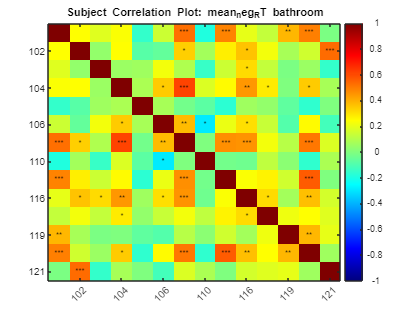

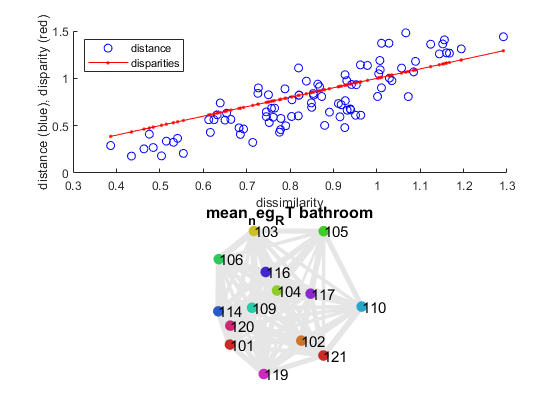

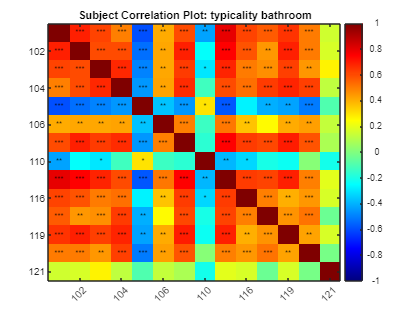

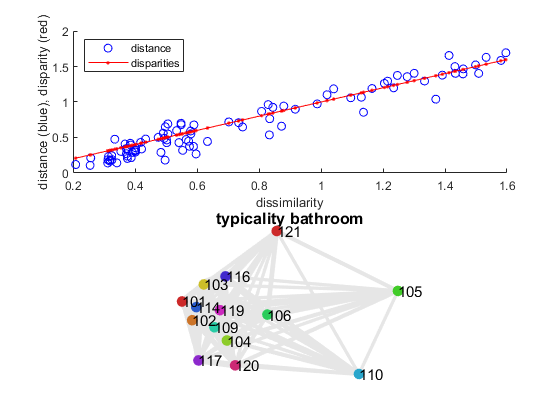

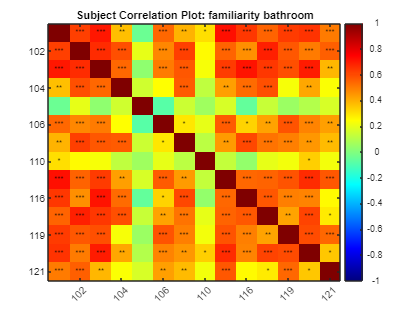

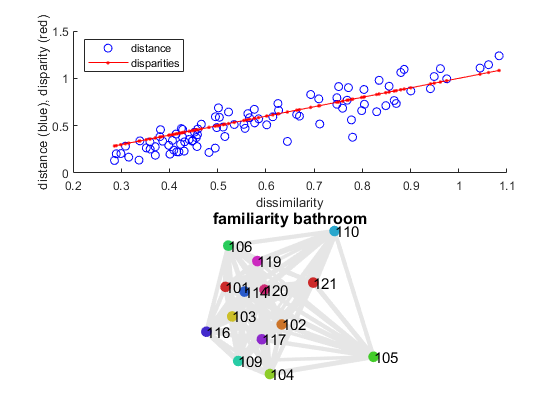

% call a costum function to calculate and plot the correlations of rating between subjects
[cor_plots, d] = intersub_cor(d2);

--- task correaltions ---

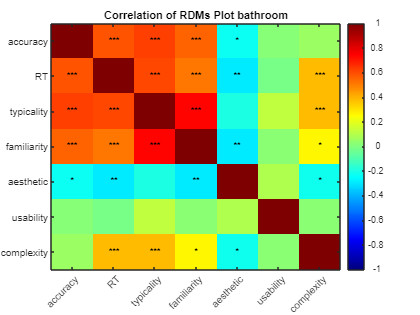

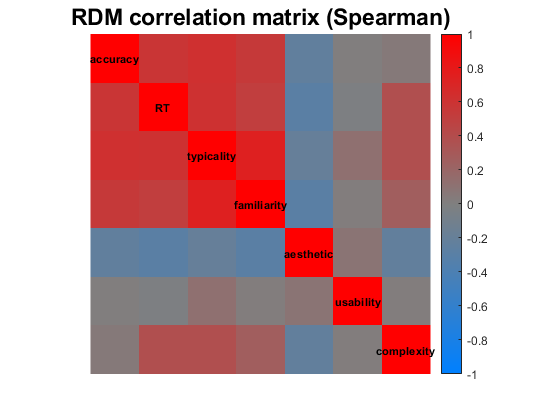

Drawing MDS arrangement for RDMs...
        "MDS of RDMs bathroom" [figure 42000000]


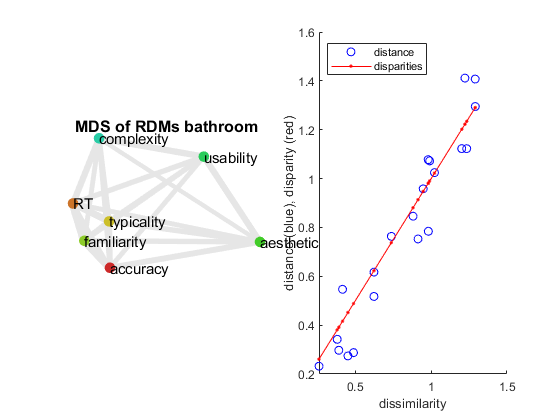

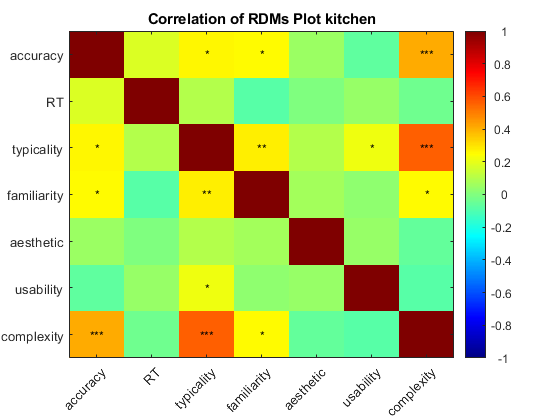

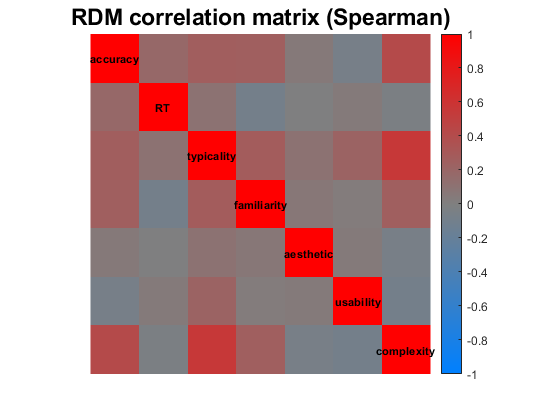

Drawing MDS arrangement for RDMs...
        "MDS of RDMs kitchen" [figure 91000000]


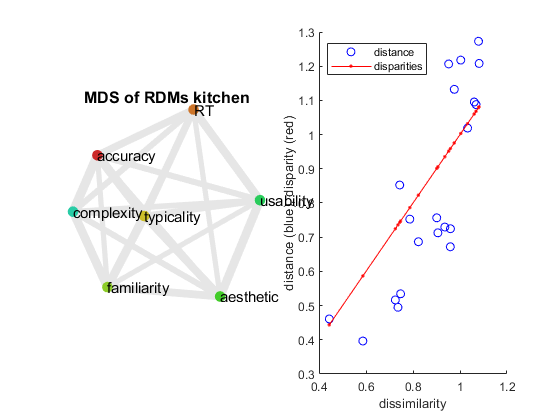

% call a costum function to calculate and plot the correlations between task RDMs
[cor_plots, d] = RDM_of_RDMs(cor_plots, d);

--- combine all measures ---

Estimating the ceiling for the average RDM correlation...
Iterative optimisation of the upper bound...
5 %10 %15 %20 %25 %(of max # iterations) Found less than 12 instances of the reference RDM.
Found less than 12 or inconsistent numbers of candidate-RDM instances. Cannot do subject random-effects inference.

Performing condition-label randomisation test of RDM relatedness (fixed effects).
1% 2% 3% 4% 5% 6% 7% 8% 9% 10% 
11% 12% 13% 14% 15% 16% 17% 18% 19% 20% 
21% 22% 23% 24% 25% 26% 27% 28% 29% 30% 
31% 32% 33% 34% 35% 36% 37% 38% 39% 40% 
41% 42% 43% 44% 45% 46% 47% 48% 49% 50% 
51% 52% 53% 54% 55% 56% 57% 58% 59% 60% 
61% 62% 63% 64% 65% 66% 67% 68% 69% 70% 
71% 72% 73% 74% 75% 76% 77% 78% 79% 80% 
81% 82% 83% 84% 85% 86% 87% 88% 89% 90% 
91% 92% 93% 94% 95% 96% 97% 98% 99% 100% 

Attempting to revert to condition-bootstrap tests comparing pairs of candidate RDMs.
there are less than 20 conditions. can not do tests for comparing pairs of candidate RDMs
Not performing any test for c

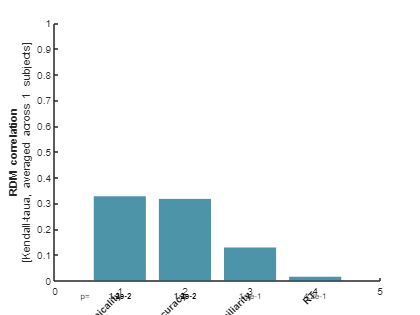

% call a costum function that combines all measures/tasks
% [cor_plots, d]  = combined(cor_plots, d);
userOptions.RDMcorrelationType='Kendall_taua';
userOptions.RDMrelatednessTest = 'subjectRFXsignedRank';
userOptions.RDMrelatednessThreshold = 0.05;
userOptions.RDMrelatednessMultipleTesting = 'FDR';
userOptions.saveFiguresPDF = 1;
userOptions.candRDMdifferencesTest = 'subjectRFXsignedRank';
userOptions.candRDMdifferencesThreshold = 0.05;
userOptions.candRDMdifferencesMultipleTesting = 'FDR';
userOptions.plotpValues = '=';
userOptions.barsOrderedByRDMCorr=true;
userOptions.resultsPath = userOptions.rootPath;
userOptions.figureIndex = [14 15];
userOptions.figure1filename = 'compareRefRDM2candRDMs_barGraph_simulatedITasRef';
userOptions.figure2filename = 'compareRefRDM2candRDMs_pValues_simulatedITasRef';

% pss = rsa.compareRefRDM2candRDMs(ref_RDM, candRDMs, userOptions);